## 向量、数组、矩阵与数据结构

### **3.1 目标：**练习向量的使用

**内容****：** f(x)=3x^5-5x^4-x^3+9x+6`，`g(x)=7x^4+5x-3`，``计算` f(x)+g(x)`，`f(x)-g(x)`，`f(x)×g(x)`，`f(x)÷g(x)。

f = [3 -5 -1 0 9 6];   
g = [7 0 0 5 -3];

result1 = f + [0 g]            % addition

result1 =      3     2    -1     0    14     3


result2 = f - [0 g]             % subtract

result2 =      3   -12    -1     0     4     9


result3 = conv(f,g)           % multiply

result3 =     21   -35    -7    15    29    52     3    45     3   -18


[result4 r] = deconv(f,g)  % divide

result4 =     0.4286   -0.7143


r =          0         0   -1.0000   -2.1429   13.8571    3.8571


### **3.2 目标：**练习数组的使用

**内容**：在数组中找出所有绝对值大于 5 的元素。

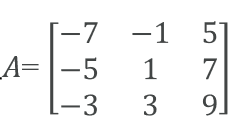

A = zeros(3,3); 
A(:) = -7:2:9; %采用“全元素”赋值法得到 A
L = abs(A)>5; %成与 A 同维的逻辑数组
B = A(L); %取出 L 中为逻辑 1 对应的 A 元素
B = B'; % 转置为行向量
disp(A);

    -7    -1     5
    -5     1     7
    -3     3     9



disp(B);

    -7     7     9



### **3.3 目标：**练习矩阵的使用

**内容：**求解方程组

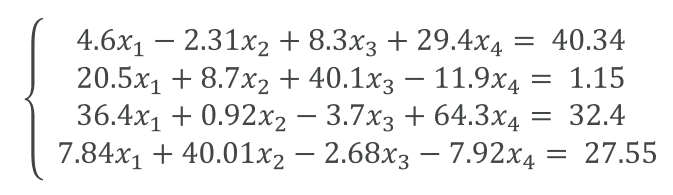

A = [4.6 -2.31 8.3 29.4; 20.5 8.7 40.1 -11.9; 36.4 0.92 -3.7 64.3; 7.84 40.01 -2.68 -7.92];
b = [40.34;1.15;32.4;27.55];
x = A\b;
disp(x')

   -1.6082    1.3572    0.9872    1.4517



### **3.4 目标：**练习元胞数组（cell arrays）的使用

**内容：**将表 3-1 所列数据存入一个 8 行 3 列的元胞数组 S 中：第 1 列为姓名，第 2 列为三门课成绩，第 3 列为总分。随后在 S 中增加一列，标明学生等级：总分 > 240 为 ‘A’；180 ≤ 总分 ≤ 240 为 ‘B’；总分 < 200 为 ‘C’。

names = ["zhao", "qian", "sun" , "li", "zhou", "wu", "zheng", "wang"];
scores = [88, 92, 74, 98, 61, 52, 82, 79; 
          95, 94, 64, 77, 41, 25, 73, 95; 
          91, 99, 81, 83, 80, 33, 79, 77];

S = cell(8,3);

for i = 1:8
    name = names(i);
    score = scores(:,i);
    total_score = sum(score);
    S(i,:) = {name, score, total_score};
end

for j = 1:size(S,1)
    total_score = S{j,3};
    % Judge grades
    if total_score > 240
        grade = {'A'};
    elseif total_score >= 180
        grade = {'B'};
    else
        grade = {'C'};
    end
    S(j,4) = grade;    
end

### **3.5 目标：**练习结构体（structure）的使用

**内容：**创建一个包含表 3-1 中 8 名学生信息的结构体，并计算这些学生的总分与平均分。

students = struct('name', {'zhao', 'qian', 'sun' , 'li', 'zhou', 'wu', 'zheng', 'wang'},...
'chinese', {88, 92, 74, 98, 61, 52, 82, 79},...
'math', {95, 94, 64, 77, 41, 25, 73, 95},...
'english', {91, 99, 81, 83, 80, 33, 79, 77});
scores = [students.chinese; students.math; students.english];
names = {students.name};
x = sum(scores);
disp('The total score of each student is:');

The total score of each student is:


disp(x);

   274   285   219   258   182   110   234   251



disp('The average score of each student is:');

The average score of each student is:


disp(x/3);

   91.3333   95.0000   73.0000   86.0000   60.6667   36.6667   78.0000   83.6667



### **3.6 目标：**练习字符串（string）的使用

**内容：**某水果店有两个仓库，存放不同种类的水果。使用集合运算找出两个仓库共有的水果、各自独有的水果，并统计两个仓库的所有水果种类。

warehouse1 = ["apple" "banana" "strawberry" "pear" "watermelon"];
warehouse2 = ["banana" "orange" "pear" "pineapple" "litchi"];
x1 = intersect(warehouse1, warehouse2);   
x2 = setdiff(warehouse1, warehouse2);     
x3 = setdiff(warehouse2, warehouse1);     
x4 = union(warehouse1, warehouse2);      
disp(x1); disp(x2); disp(x3); disp(x4)

    "banana"    "pear"

    "apple"    "strawberry"    "watermelon"

    "litchi"    "orange"    "pineapple"

    "apple"    "banana"    "litchi"    "orange"    "pear"    "pineapple"    "strawberry"    "watermelon"



### **3.7 目标：**练习表格（tables）的使用

**内容：**从 Excel 表格读取股票数据，存入 table；计算最高价与最低价的平均值，作为新列添加到表中；再计算收盘价与开盘价的绝对差值，也作为新列添加；最后显示第三天的数据。

% 读取Excel文件
data = readtable('data.xlsx'); 

% 添加平均价格列（最高价与最低价的平均值）
data.average = (data.high + data.low) / 2;

% 添加价格差异列（收盘价与开盘价的绝对差值）
data.difference = abs(data.close - data.open);

% 显示第三天的数据
disp(data(3,:));

       date        open     high     low     close    average    difference
    ___________    _____    _____    ____    _____    _______    __________

    03-Mar-2024    35.18    35.31    34.5    35.16    34.905        0.02   



### **3.8 目标：**练习排序（sort）与索引（index）的使用

**内容：**在实验 3.5 得到学生总分后，按总分从高到低排序，并依次打印这些学生的姓名。

students = struct('name', {'zhao', 'qian', 'sun' , 'li', 'zhou', 'wu', 'zheng', 'wang'},...
    'chinese', {88, 92, 74, 98, 61, 52, 82, 79},...
    'math', {95, 94, 64, 77, 41, 25, 73, 95},...
    'english', {91, 99, 81, 83, 80, 33, 79, 77});
names = {students.name};
scores = [students.chinese; students.math; students.english];
x = sum(scores);
disp('The total score of each student is:');

The total score of each student is:


disp(x);

   274   285   219   258   182   110   234   251



[B,sy] = sort(x, 'descend');
disp('The ranking is:')

The ranking is:


for i = 1:8
    e = B(i);
    d = find(x==e);
    disp(names(d))
end

    {'qian'}

    {'zhao'}

    {'li'}

    {'wang'}

    {'zheng'}

    {'sun'}

    {'zhou'}

    {'wu'}



### **练习**

如下图所示，数独是一个 9×9 方阵，由 9 个宫（每个宫为 3×3 方块）组成。请验证下图所示数独是否同时满足：

（1）每行包含 1–9 不重复的数字；

（2）每列包含 1–9 不重复的数字；

（3）每个宫包含 1–9 不重复的数字。